#### Test Case 1: Single Community (Node)

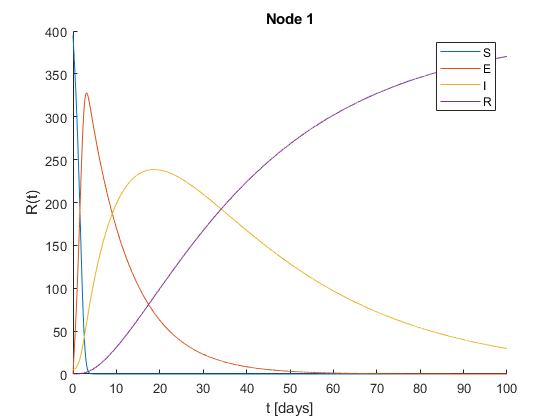

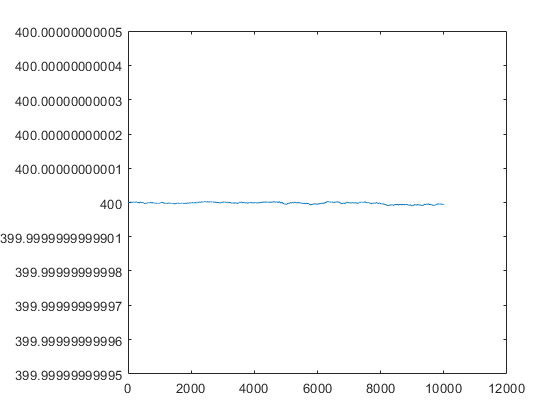

P = 1;    % # nodes simulated; for current setting o
t_start = 0;
t_stop = 100;
timestep = 0.01;

%select input evaluation function
eval_u = 'GenInputVec';
%select model evaluation function
eval_f = 'EVALF';

theta = zeros(P,P);

%start state at time 0 equals input vector at time 0
x_start = GenInputVec(P, 0);
p = GenPStruct(P, theta);

% test FE function
[X] = ForwardEuler(P, eval_f, x_start, p, eval_u, t_start, t_stop, timestep);

% Calculate total number of people
%% Plot SEIR curves for all nodes
for i = 1:size(X,1)
	S = X(i,:);
	s = [S{1:end}];
	N = sum(s, 1);
	figure(i);
	hold on;
	days = linspace(t_start,t_stop,length(s(1,1:end)));
	plot(days, s(1,1:end));
	xlabel('t [days]'); ylabel('S(t)');
	
	plot(days, s(2,1:end));
	xlabel('t [days]'); ylabel('E(t)');
	
	plot(days, s(3,1:end));
	xlabel('t [days]'); ylabel('I(t)');
	
	plot(days, s(4,1:end));
	xlabel('t [days]'); ylabel('R(t)');
	hold off;
	legend('S','E','I','R');
	title(['Node ',num2str(i)])
	
	figure;
	plot(N); hold on;
end

#### Test Case 2: 10 Communities (No Inter-Node Transmission)

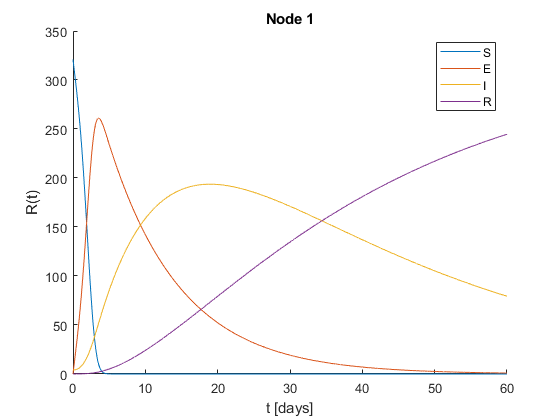

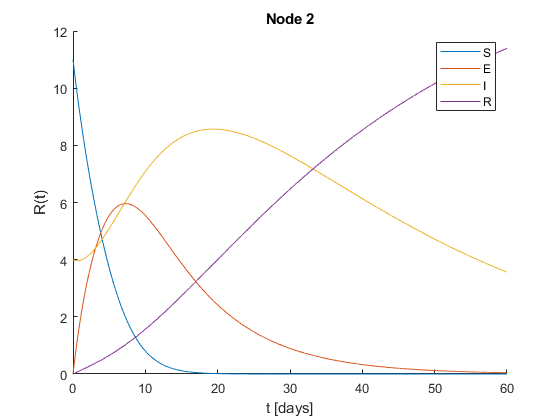

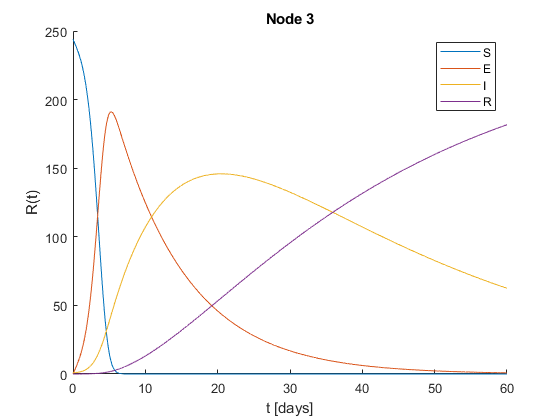

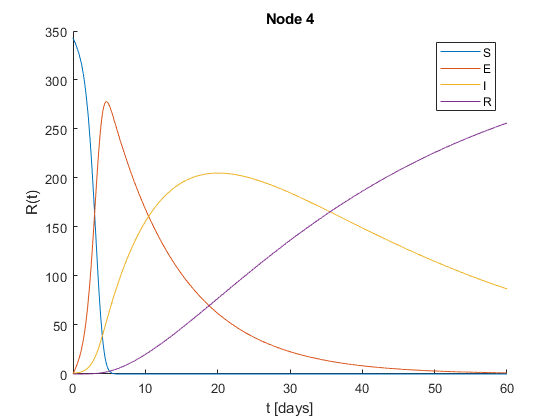

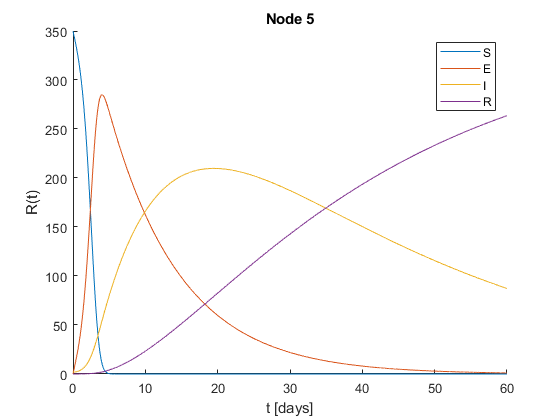

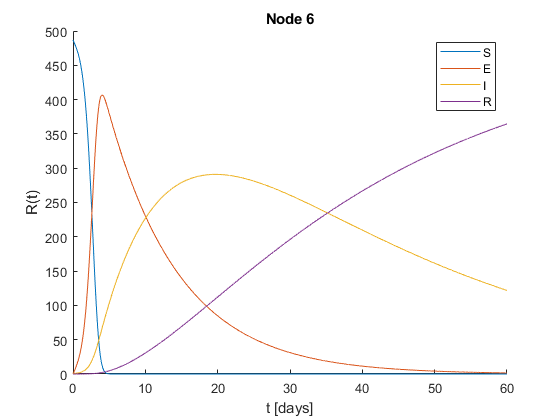

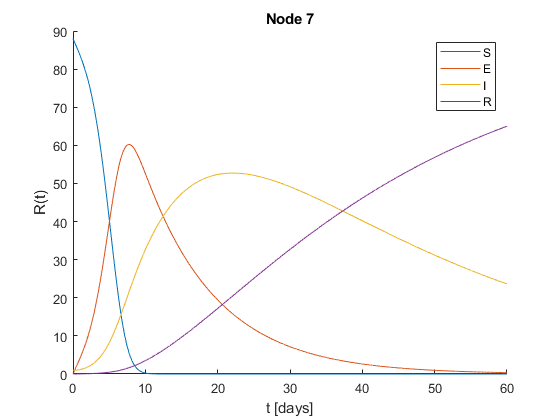

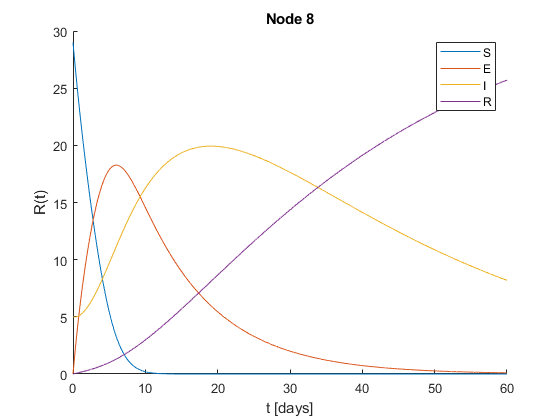

clear; close all;
P = 10;    % # nodes simulated; for current setting o
t_start = 0;
t_stop = 60;
timestep = 0.01;

%select input evaluation function
eval_u = 'GenInputVec';
%select model evaluation function
eval_f = 'EVALF';

theta = zeros(P,P);

%start state at time 0 equals input vector at time 0
x_start = GenInputVec(P, 0);
p = GenPStruct(P, theta);

% test FE function
[X] = ForwardEuler(P, eval_f, x_start, p, eval_u, t_start, t_stop, timestep);

%% Plot SEIR curves for all nodes
for i = 1:size(X,1)
	S = X(i,:);
	s = [S{1:end}];
	N(i,:) = sum(s, 1);
	figure(i);
	hold on;
	days = linspace(t_start,t_stop,length(s(1,1:end)));
	plot(days, s(1,1:end));
	xlabel('t [days]'); ylabel('S(t)');
	
	plot(days, s(2,1:end));
	xlabel('t [days]'); ylabel('E(t)');
	
	plot(days, s(3,1:end));
	xlabel('t [days]'); ylabel('I(t)');
	
	plot(days, s(4,1:end));
	xlabel('t [days]'); ylabel('R(t)');
	hold off;
	legend('S','E','I','R');
	title(['Node ',num2str(i)])
	
end

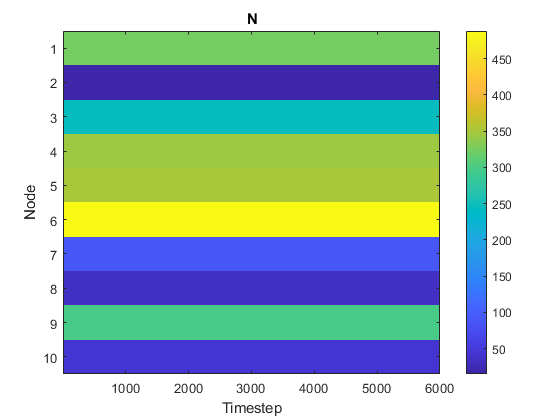

figure; imagesc(N(:,:)); title('N'); xlabel('Timestep'); ylabel('Node'); colorbar;

#### Test Case 3: 10 Communities (With Inter-Node Transmission)

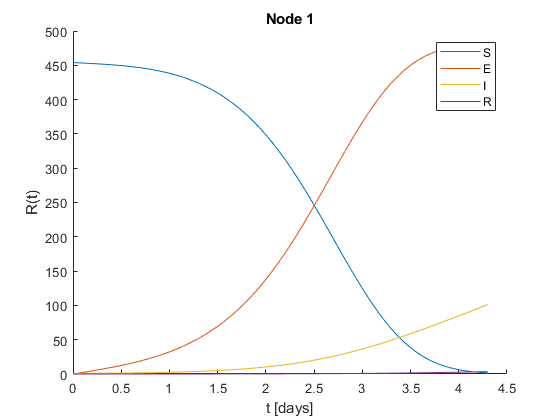

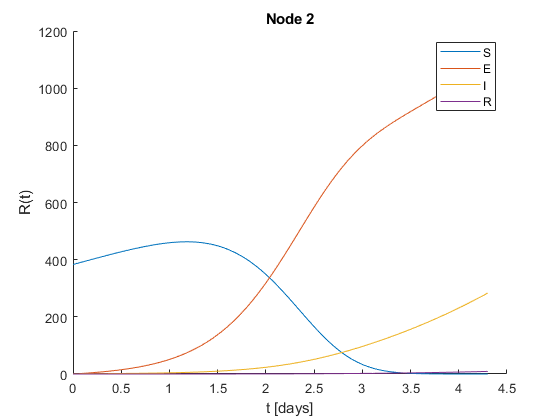

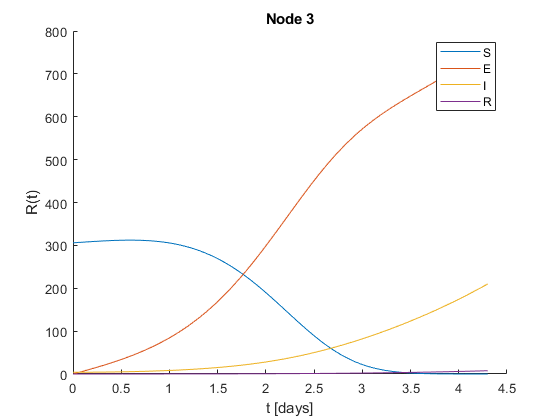

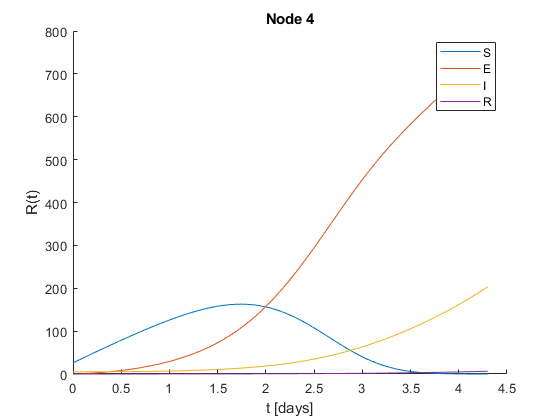

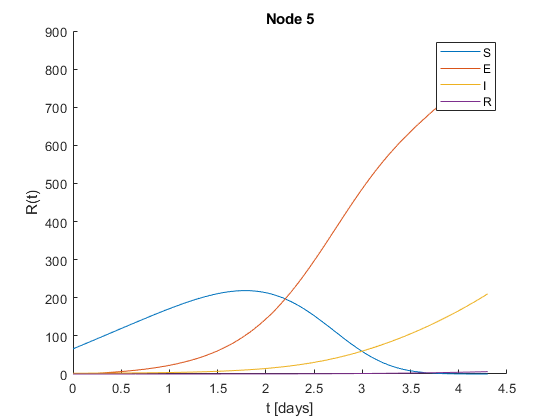

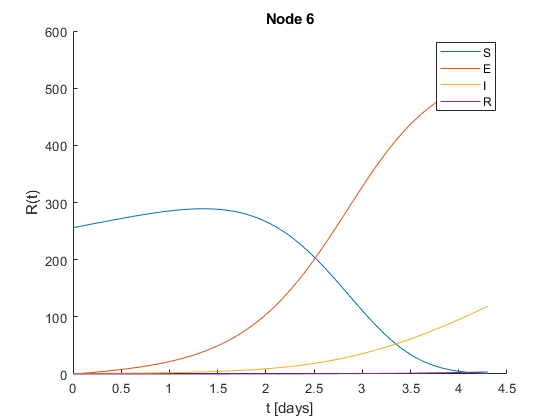

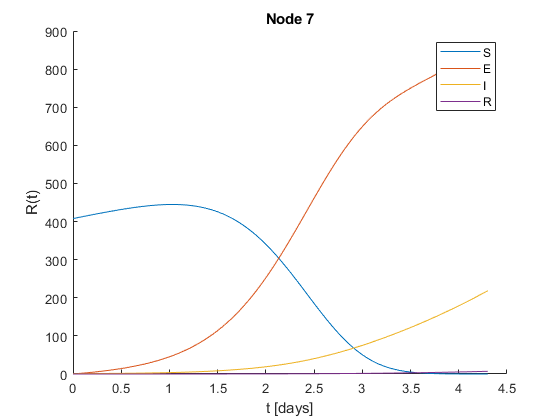

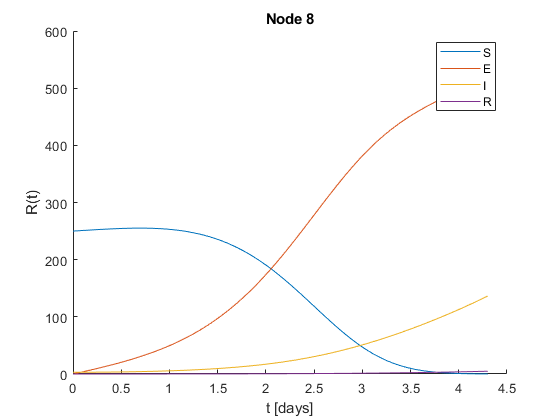

clear; close all;
P = 10;    % # nodes simulated; for current setting o
t_start = 0;
t_stop = 4.3;
timestep = 0.01;

%select input evaluation function
eval_u = 'GenInputVec';
%select model evaluation function
eval_f = 'EVALF';

theta = GenThetaMat(P, 'symmetric');

%start state at time 0 equals input vector at time 0
x_start = GenInputVec(P, 0);
p = GenPStruct(P, theta);

% test FE function
[X] = ForwardEuler(P, eval_f, x_start, p, eval_u, t_start, t_stop, timestep);

%% Plot SEIR curves for all nodes
for i = 1:size(X,1)
	S = X(i,:);
	s = [S{1:end}];
	N(i,:) = sum(s, 1);
	figure(i);
	hold on;
	days = linspace(t_start,t_stop,length(s(1,1:end)));
	plot(days, s(1,1:end));
	xlabel('t [days]'); ylabel('S(t)');
	
	plot(days, s(2,1:end));
	xlabel('t [days]'); ylabel('E(t)');
	
	plot(days, s(3,1:end));
	xlabel('t [days]'); ylabel('I(t)');
	
	plot(days, s(4,1:end));
	xlabel('t [days]'); ylabel('R(t)');
	hold off;
	legend('S','E','I','R');
	title(['Node ',num2str(i)])
	
end

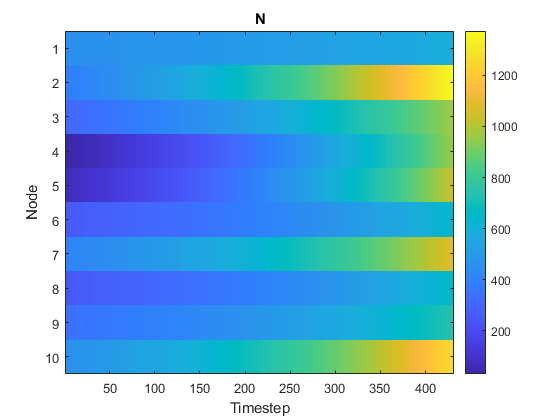

figure; imagesc(N(:,:)); title('N'); xlabel('Timestep'); ylabel('Node'); colorbar;

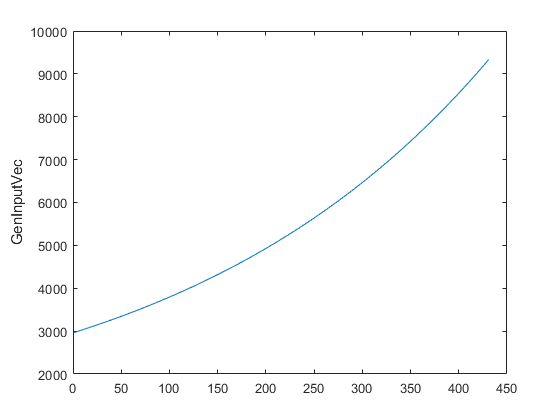


Nsum = sum(N,1);
figure; plot(Nsum); ylabel(eval_u)

#### Test Case 4: 10 Communities (Net Zero Inter-Node Transmission)

#### Test Case 5: 100 Communities (Net Zero Inter-Node Transmission)